# Week 8 Problem 3

* Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

Problem 3 asks us to use the MATLAB robotics toolbox's `forwardDynamics` function to model the resultant joint accelerations of a manipulator when external forces are applied to it. We are first to run the example code given for the Kuka LBR manipulator in the provided link and then apply the `forwardDynamics` function to the Sawyer/Baxter robot defined in last week's assignment. 

### Approach:

The approach is to first run the example code given in the link provided for the Kuka LBR robot and compute the joint torque required to balance the external forces acting on the manipulator in this static system. We can than vary the forces acting on the manipulator (dynamics) and produce plots of the joint torques as the external force profile varies for each joint. Finally, we can apply the same to the Sawyer/Baxter arm from last week's assignment.    

## Materials and Methods:

The premise of this assignment is to compute the torques needed at each joint to maintain balance with external forces acting on the manipulator in order to maintain the desired configuration. 

We begin by copying and running the code for the Kuka LBR robot model example given in the `forwardDynamics` documentation. First, we call the `lbr` robot example and specify the dataformat as 'row', assign the home configuration to a variable `q` and show the robot in this home configuration.

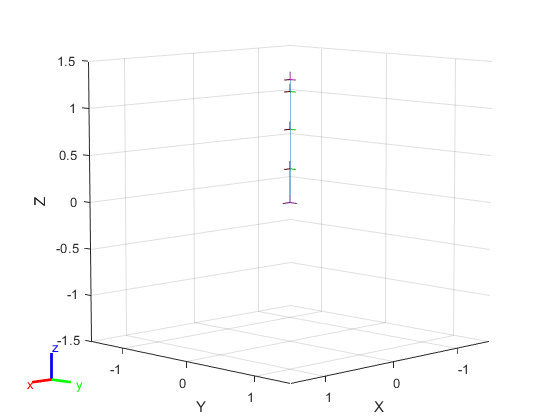

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% NOTE: The code is a tad tempermental from run-to-run
% If it throws errors, try running section by section. 
% I've done my best to debug this and It seems to be working
% But I'm not 100% that clicking "Run" will work flawlessly every time for
% some reason
clear all

load exampleRobots.mat lbr
lbr.DataFormat = 'row';
q = homeConfiguration(lbr);
show(lbr,q)

For context, the Kuka robot is a 7DoF robot consisting of all revolute joints. A tool may be attached at the end effector, but is shown below without tool for reference.

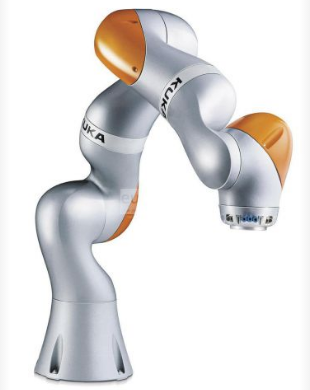

There are several different models available that differ in link length but the makeup of the Kuka LBR is largely the same across all models. From Faria et al. the DH table for a Kuka robot is given as, for reference:

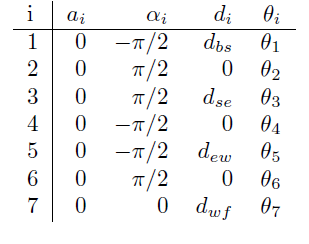

With this in mind, we can continue to implement the example code for this manipulator and specify the external forces acting on the robot.

lbr.Gravity = [0 0 -9.81];
wrench = [0 0 0.5 0 0 0.3];
fext = externalForce(lbr,'tool0',wrench,q);
qddot = forwardDynamics(lbr,q,[],[],fext)

qddot =    -0.0000    0.0077   -0.0000    0.0092    0.0000    0.0014    0.2500


tau = inverseDynamics(lbr,q,[],[],fext)

tau =    -0.5000   -0.0213   -0.5000         0   -0.5000         0   -0.5000


We define the force gravity to be $-9\ldotp 81\frac{m}{s^2 }$ in the base frame *z* direction for the robot model. Gravity applies to all links and joints of the robot. `wrench` is a force array consisting of the torques and forces applied to the body, specified as a `[Tx Ty Tz Fx Fy Fz]` vector. The first three elements of the wrench correspond to the moments around *xyz*-axes. The last three elements are linear forces along the same axes. As it is defined in the example, we have a nonzero *z *moment and force acting on the `tool0` end effector body for a given configuration `q` as specified by `fext`.

We compute the acceleration of the joints given the presence of these external forces for our given configuration *q. *The function `forwardDynamics` is called and outputs a *1xn* array of accelerations, where *n* is the number of links. Each position in this array corresponds to its respective joint. Note that the computation for joint acceleration given above assumes no torques or joint velocities present at each joint.

Finally, we can compute the joint torques required to balance the external forces applied to the manipulator by calling `inverseDynamics`. The output of `inverseDynamics`, `tau`, is also a 1xn array of torques, with each position corresponding to its respective joint. Note that as shown above, the inverseDynamics computation of tau for each joint assumes no joint velocities or accelerations occuring. 

With this static system understood, we can now write code to create a profile of the external forces (`wrench`) experienced by the manipulator and plot the resultant acceleration and torque profiles of each joint as the manipulator responds to the external forces applied for the given configuration. 

For example, we may define `wrench as a linspace` that contains values linearly spaced between upper and lower bounds. Below, we can define these bounds with sliders to explore the effects of varying the range of forces applied to the end effector of the manipulator. 

%%%%%%%%%%%%%%Config Control%%%%%%%%%%%%%%%%%%%%%
Config_Setting = "Random Config"

Config_Setting = "Random Config"

%Controls the config setting of the robot, either home or random
%n.b. a random setting is always different
%Interesting to see the effects of forces on different configurations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Logic for switch to define q
if Config_Setting == "Home Config"
    q = homeConfiguration(lbr);
elseif Config_Setting == "Random Config"
    q = randomConfiguration(lbr);
end

%moment sliders
Tx_lower =0.5;
Tx_upper = Tx_lower + 0.5;
Ty_lower = 0.6;
Ty_upper = Ty_lower + 0.2;
Tz_lower = 0.4;
Tz_upper = Tz_lower + 0.5;

%force sliders
Fx_lower =0.6;
Fx_upper = Fx_lower + 0.8;
Fy_lower = 0.7;
Fy_upper = Fy_lower + 0.8;
Fz_lower = 0.4;
Fz_upper = Fz_lower + 0.9;


With these defined, we can specify the `linspaces` for each wrench array position

Tx = linspace(Tx_lower,Tx_upper,100);
Ty = linspace(Tx_lower,Tx_upper,100);
Tz = linspace(Tx_lower,Tx_upper,100);
Fx = linspace(Tx_lower,Tx_upper,100);
Fy = linspace(Tx_lower,Tx_upper,100);
Fz = linspace(Tx_lower,Tx_upper,100);

We can iterate over each step in the moment/force arrays defined above and use either the home configuration shown previously or place the robot into a random configuration to study what the effect of varying the configuration has on the individual joint torques.

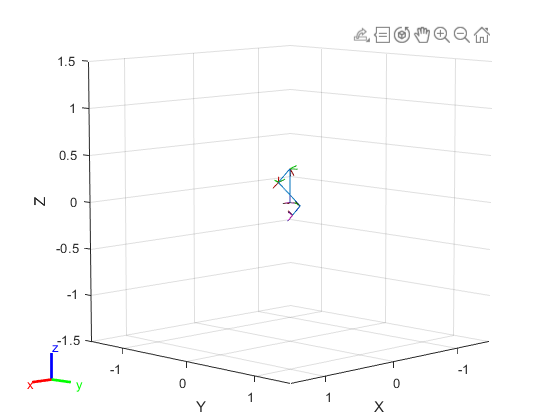

%define lbr and show config
load exampleRobots.mat lbr
lbr.DataFormat = 'row';
show(lbr, q);


%set up gravity
lbr.Gravity = [0 0 -9.81];

%some pre-defining of variables for the loop
force_count = length(Tx);
tau_holder = zeros(force_count,7);
accel_holder = zeros(force_count,7);

%loop over the force/moment steps
for i = 1:force_count
    %define wrench array
    wrench = [Tx(i),Ty(i),Tz(i),Fx(i),Fy(i),Fz(i)];
    %get fext matrix
    fext = externalForce(lbr,'tool0',wrench,q);
    
    %get accel and tau
    qddot = forwardDynamics(lbr,q,[],[],fext);
    tau = inverseDynamics(lbr,q,[],[],fext);
    
    %assign current tau and accel to rows in the holder matricies
    tau_holder(i,:) = tau;
    accel_holder(i,:) = qddot;
end

Plotting the toque at the joints yields

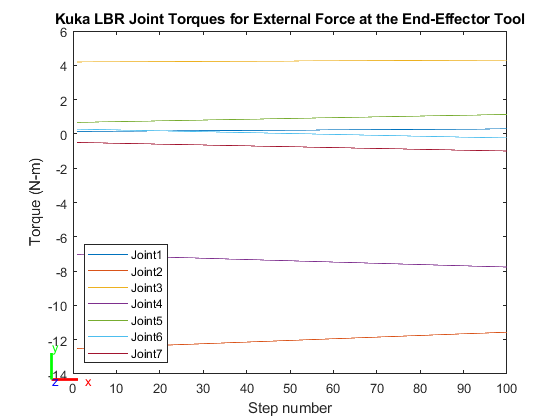

force_counter = linspace(1,force_count,100);

plot(force_counter,tau_holder(:,1), force_counter,tau_holder(:,2),force_counter,...
    tau_holder(:,3),force_counter,tau_holder(:,4),force_counter,tau_holder(:,5),...
    force_counter, tau_holder(:,6), force_counter, tau_holder(:,7));
title("Kuka LBR Joint Torques for External Force at the End-Effector Tool");
xlabel("Step number");
ylabel("Torque (N-m)");
legend("Joint1", "Joint2", "Joint3", "Joint4", "Joint5", "Joint6", "Joint7",'Location',"southwest");

Plotting the acceleration at the joints yields:

force_counter = linspace(1,force_count,100);

plot(force_counter,accel_holder(:,1), force_counter,accel_holder(:,2),force_counter,...
    accel_holder(:,3),force_counter,accel_holder(:,4),force_counter,accel_holder(:,5),...
    force_counter, accel_holder(:,6), force_counter, accel_holder(:,7));
title("Kuka LBR Joint Accels for External Force at the End-Effector Tool");
xlabel("Step number");
ylabel("Acceleration (m/s^2)");
legend("Joint1", "Joint2", "Joint3", "Joint4", "Joint5", "Joint6", "Joint7",'Location',"southwest");

With the tutorial robot's torque and joint acceleration modelled in MATLAB, we now can apply the same treatment to the Sawyer/Baxter arm from the Week 7 assignment and produce similar plots.

## Results:    

We start by defining the DH parameter table for the Baxter robot. Faria et al. provides the table and the accompanying DH diagram.

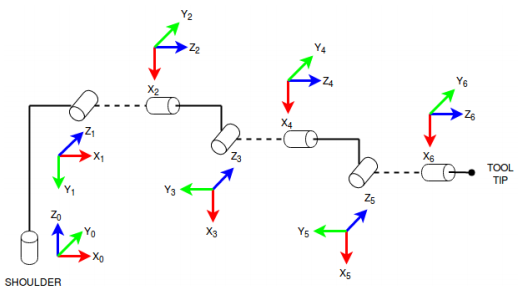

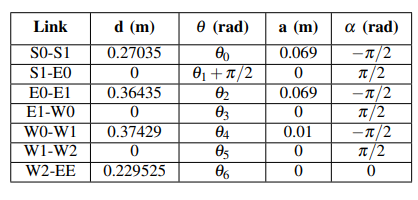

syms 'a%d' 'alpha%d' 'd%d' 'theta%d' [1 7]

%DH table as per Kumar et al.
dh = [
    a1  -pi/2   d1    theta1;
    0    pi/2   0     theta2+pi/2;
    a3  -pi/2   d3    theta3;
    0    pi/2   0     theta4;
    a5  -pi/2   d5    theta5;
    0    pi/2   0     theta6;
    0    0      d7    theta7;
    ]

$$dh = \left(\begin{array}{cccc} a_{1} & -\frac{\pi }{2} & d_{1} & \theta_{1}\\ 0 & \frac{\pi }{2} & 0 & \theta_{2}+\frac{\pi }{2}\\ a_{3} & -\frac{\pi }{2} & d_{3} & \theta_{3}\\ 0 & \frac{\pi }{2} & 0 & \theta_{4}\\ a_{5} & -\frac{\pi }{2} & d_{5} & \theta_{5}\\ 0 & \frac{\pi }{2} & 0 & \theta_{6}\\ 0 & 0 & d_{7} & \theta_{7} \end{array}\right)$$


[a, alpha, d, theta]=initialize_dh_params(dh, a, alpha, d, theta);
[full_xform, successive_frame_xforms,base_to_frame_xforms] = create_A_0_n_matrix(a,alpha,d,theta);

First, The function `initialize_dh_params` simply replaces the symbols in the arrays `a, alpha, d, theta` with the values or symbols from the dh table. 

The function `create_A_0_n_matri`x was created largely by Ezekiel Flaton and computes each individual successive 4x4 homogeneous$A_j^i$ matrix, the full transformation matrix $A_n^0$ and the base-to-frame matricies $A_i^0$. It takes the dh parameters arrays $a,\alpha ,d,\theta$  as inputs and outputs the A matricies in arrays. The function calculates the number of links in the DH parameter arrays and assigns size this to the loop counter variable.

`create_A_0_n_matrix` calls a function `create_dh_matrix `in a loop starting at the $A_i^0$ matrix to compute the 4x4 standard DH matrix that transforms from one coordinate frame to the next for each link. It stores the resulting matrix in an array `A_i_array`. The `dh_matrix` is then multiplied by `intermediate_matrix,`which has stored the last matrix calculated in the loop, to get the transformation from the base frame to the *ith* coordinate frame. This base-to-frame transformation is stored in the `A_0_i_matrix` array. Finally, the last matrix held in `dh_intermediate_matrix` is assigned to the output `A_0_n` which represents the transformation from the base frame to the end effector.

We can sub in the link lengths from Kumar et al. 

%actual link lengths from Kumar et al.
d1 = 0.27035;
d3 = 0.36435;
d5 = 0.37429;
d7 = 0.229525; 
a1 = 0.069;
a3= 0.069;
a5 = 0.01;
theta1 = 0;
theta2 = 0;
theta3 = 0;
theta4 = 0;
theta5 = 0;
theta6 = 0;
theta7 = 0;

%Sub in values
dh_table_w_values = double(subs(dh))

dh_table_w_values =     0.0690   -1.5708    0.2703         0
         0    1.5708         0    1.5708
    0.0690   -1.5708    0.3644         0
         0    1.5708         0         0
    0.0100   -1.5708    0.3743         0
         0    1.5708         0         0
         0         0    0.2295         0


Finally, we can construct the `baxter` robot from the DH parameter table. 

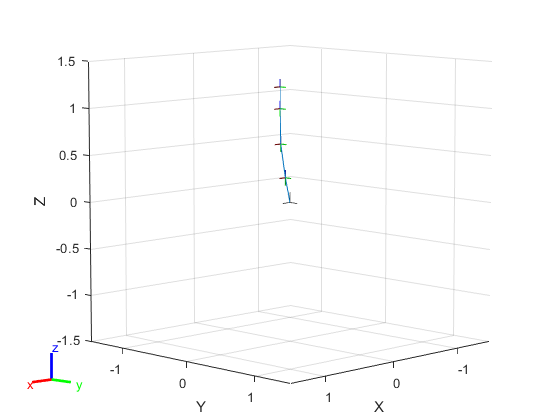

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%create array of joint type strings
joint_array_baxter=strings(1,7);
for i = 1:length(joint_array_baxter)
    joint_array_baxter(i) = 'revolute';
end

%instantiate baxter object
baxter = robotics.RigidBodyTree();

%run our build-a-robot function
construct_rigid_body_robot(baxter,dh_table_w_values,joint_array_baxter);

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(baxter)

We define our robot object to be `baxter` using the robotics toolbox. Then, using the `construct_rigid_body_robot` function we pass the `baxter` object, the numerically defined DH table and the array of joint type strings to define baxter as an *ith*-link serial robot based on the size of the `joint_array_type` passed to it. In this case *i *=7 as baxter is a 7 link manipulator.

`construct_rigid_body_robot` was a function created by the author to automate the routine to define a serial rigid body robot object using the MATLAB robotics toolbox. The function first uses the length of the joint type array to calculate the number of links that need to be created and instantiates the number of required bodies and joints. Then, from the DH parameter table passed to the function, the `setFixedTransform` function assigns the appropriate *ith* DH table row to the *ith* link joint. With the inter-joint transformations defined, the bodies are then associated to their appropriate joints. Finally, the robot is constructed using the `addBody` function to specify the connections between successive bodies. The robot is then set to the home configuration and is finally displayed.

%%%%%%%%%%%%%%Config Control%%%%%%%%%%%%%%%%%%%%%
Config_Setting_Bax = "Random Config"

Config_Setting_Bax = "Random Config"

%Controls the config setting of the robot, either home or random
%n.b. a random setting is always different
%Interesting to see the effects of forces on different configurations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Logic for switch to define q
if Config_Setting_Bax == "Home Config"
    q_bax = homeConfiguration(baxter);
elseif Config_Setting_Bax == "Random Config"
    q_bax = randomConfiguration(baxter);
end

%needed to convert the struct to an array for some reason 
q_bax_array = [q_bax(1:7).JointPosition];

%moment sliders
Tx_lower_Bax =0.5;
Tx_upper_Bax = Tx_lower_Bax + 0.5;
Ty_lower_Bax = 0.6;
Ty_upper_Bax = Ty_lower_Bax + 0.2;
Tz_lower_Bax = 0.4;
Tz_upper_Bax = Tz_lower_Bax + 0.5;

%force sliders
Fx_lower_Bax =0.6;
Fx_upper_Bax = Fx_lower_Bax + 0.8;
Fy_lower_Bax = 0.7;
Fy_upper_Bax = Fy_lower_Bax + 0.8;
Fz_lower_Bax = 0.4;
Fz_upper_Bax = Fz_lower_Bax + 0.9;

With these defined, we can specify the `linspaces` for each wrench array position

Tx_Bax = linspace(Tx_lower,Tx_upper,100);
Ty_Bax = linspace(Tx_lower,Tx_upper,100);
Tz_Bax = linspace(Tx_lower,Tx_upper,100);
Fx_Bax = linspace(Tx_lower,Tx_upper,100);
Fy_Bax = linspace(Tx_lower,Tx_upper,100);
Fz_Bax = linspace(Tx_lower,Tx_upper,100);

We can iterate over each step in the moment/force arrays defined above and use either the home configuration shown previously or place the robot into a random configuration to study what the effect of varying the configuration has on the individual joint torques.

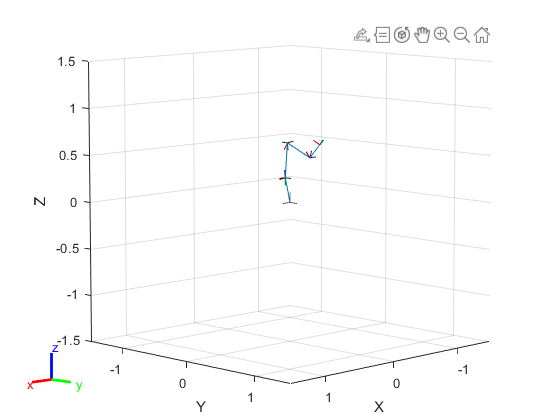

show(baxter, q_bax);

baxter.DataFormat = 'row';

%set up gravity
baxter.Gravity = [0 0 -9.81];

%some pre-defining of variables for the loop
force_count_Bax = length(Tx_Bax);
tau_holder_Bax = zeros(force_count_Bax,7);
accel_holder_Bax = zeros(force_count_Bax,7);

%loop over the force/moment steps
for i = 1:force_count_Bax
    %define wrench array
    wrench_Bax = [Tx_Bax(i),Ty_Bax(i),Tz_Bax(i),Fx_Bax(i),Fy_Bax(i),Fz_Bax(i)];
    %get fext matrix
    fext_Bax = externalForce(baxter,'body7',wrench_Bax,q_bax_array);
    
    %get accel and tau
    qddot_Bax = forwardDynamics(baxter,q_bax_array,[],[],fext_Bax);
    tau_Bax = inverseDynamics(baxter,q_bax_array,[],[],fext_Bax);
    
    %assign current tau and accel to rows in the holder matricies
    tau_holder_Bax(i,:) = tau_Bax;
    accel_holder_Bax(i,:) = qddot_Bax;
end

Plotting the toque at the joints yields

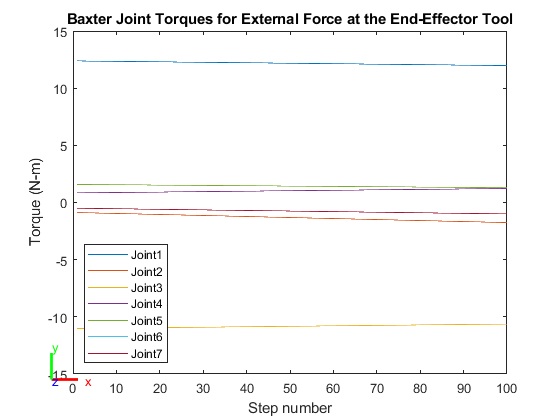

force_counter_Bax = linspace(1,force_count_Bax,100);

plot(force_counter_Bax,tau_holder_Bax(:,1), force_counter_Bax,tau_holder_Bax(:,2),force_counter_Bax,...
    tau_holder_Bax(:,3),force_counter_Bax,tau_holder_Bax(:,4),force_counter_Bax,tau_holder_Bax(:,5),...
    force_counter_Bax, tau_holder_Bax(:,6), force_counter_Bax, tau_holder_Bax(:,7));
title("Baxter Joint Torques for External Force at the End-Effector Tool");
xlabel("Step number");
ylabel("Torque (N-m)");
legend("Joint1", "Joint2", "Joint3", "Joint4", "Joint5", "Joint6", "Joint7",'Location',"southwest");

Plotting the acceleration at the joints yields:

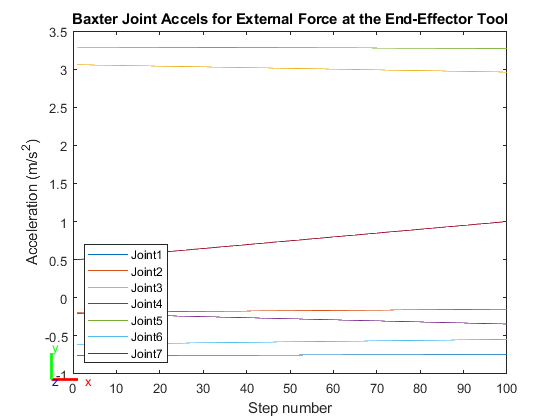

force_counter_Bax = linspace(1,force_count_Bax,100);

plot(force_counter_Bax,accel_holder_Bax(:,1), force_counter_Bax,accel_holder_Bax(:,2),force_counter_Bax,...
    accel_holder_Bax(:,3),force_counter_Bax,accel_holder_Bax(:,4),force_counter_Bax,accel_holder_Bax(:,5),...
    force_counter_Bax, accel_holder_Bax(:,6), force_counter_Bax, accel_holder_Bax(:,7));
title("Baxter Joint Accels for External Force at the End-Effector Tool");
xlabel("Step number");
ylabel("Acceleration (m/s^2)");
legend("Joint1", "Joint2", "Joint3", "Joint4", "Joint5", "Joint6", "Joint7",'Location',"southwest");

## Discussion:

Both the Kuka LBR and the Baxter Robot arm's individual joint torques and accelerations were successfully modeled and plotted for varying external forces. With both manipulator models, the configuration may be varied to explore how changing the configuration of the robot affects how the robot's individual joints balance themselves against the external forces presented to the end effector. 

The results of the analysis make intuitive sense. In all cases, when the end effector of either manipulator is subjected to linearly varying (increasing) forces and moments in x, y and z, the resulting individual joint torques vary linearly as each force profile is stepped through and evaluated. 

The external force profiles defined for either manipulator are relatively simple as opposed to defining the force profiles to be a more complex function. This was delibrate as I wanted to ensure and show that the output would be predictable in behavior and intuitive.

The most interesting aspect of this modelling exercise is the included option to choose a random configuration. The delibrate section break immediately after the selector switch enables the individual force and moment sliders to be exercised without rerunning the program and losing the configuration, as the random configuration obtained is lost on a subsequent run. 

From plotting subsequent runs of random configurations and adjusting the sliders, it is apparent that the acceleration and torque of the individual joints in response to the external forces can vary greatly in magnitude and direction (positive or negative trending) depending on the configuration of the manipulator.

It would be interesting to define a more complex (sinusoidal, trapezoidal, etc) external force profile and plot the resulting individual joint torque and acceleration for each manipulator. Further work may be done to define and plot the individual joint's torque and acceleration for a varying force and moment profile while the manipulator is made to step through a trajectory profile, as this would probably be a likely scenario for the manipulator when used in a real-world setting during a typical use-case operation.

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (pp. 35-74) (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- Faria, Carlos & Ferreira, Flora & Erlhagen, Wolfram & Monteiro, Sérgio & Bicho, Estela. (2018). Position-based kinematics for 7-DoF serial manipulators with global configuration 

- R.L. Williams II, “Baxter Humanoid Robot Kinematics”, Internet Publication, https://www.ohio.edu/mechanical-faculty/williams/html/pdf/BaxterKinematics.pdf, April 2017. 

- Akshay Kumar et al, “Baxter Humanoid Robot Kinematics”, Internet Publication,https://kumarakshay.me/images/mykdl/baxter-kdl-project.pdf

## Defined Functions

function r_matrix = create_rotation_matrix(x, y, z)
    % This function creates a rotation matrix using roll (z), pitch (y),
    % and yaw (x) angles
    r_x_matrix = [1 0 0 ; 0 cos(x) -sin(x) ; 0 sin(x) cos(x)];
    r_y_matrix = [cos(y) 0 sin(y); 0 1 0; -sin(y) 0 cos(y)];
    r_z_matrix = [cos(z) -sin(z) 0; sin(z) cos(z) 0; 0 0 1];
    r_matrix = r_z_matrix * r_y_matrix * r_x_matrix;
end

function h_matrix = create_homogenous_matrix(x,y,z,dx,dy,dz)
    r_matrix = create_rotation_matrix(x,y,z);
    d_vector = [dx; dy; dz];
    h_matrix = [r_matrix d_vector; 0 0 0 1];
end

function dh_matrix = create_dh_matrix(a, alpha, d, theta)
    dh_matrix = [
      cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
      sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
      0,          sin(alpha),           cos(alpha),             d;
      0,            0,                  0,                      1];
end

function [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta)
    % This function creates several dh transformation matrices and
    % multiplies them together to give one final transformation matrix
    % Inputs are 1xn matrices representing the dh params for each link
    % Output is a 4x4 dh matrix representing the ovrall transform for all
    % given links
    
    % Find the umber of links by finding the length of the array theta
    number_of_links = size(theta,2);
    % Ensure that the arrays for alpha, a, and d are the same size as theta
    if (size(alpha,2)==number_of_links)&&(size(a,2)==number_of_links)&&(size(d,2)==number_of_links)
        
        % Start off by creating a symbolic dh matrix that is 4x4xn
        % Each 4x4 matrix will represent 1 step of the transform and there
        % will be n transforms for the n links
        A_i_array = sym("dh_matrix_array", [4,4,number_of_links]);
        
        % Initialize an identity matrix to calculate the ifinal dh
        % transform on the fly
        dh_intermediate_matrix = eye(4,4);
        for i=1:number_of_links
            dh_matrix = create_dh_matrix(a(i), alpha(i), d(i), theta(i)); % Create the dh matrix for link i
            A_i_array(:,:,i) = dh_matrix; % Assign that dh_matrix to our 4x4xn matrix at index i
            dh_intermediate_matrix = dh_intermediate_matrix * dh_matrix; % Get the full transform up to this point
            A_0_i_array(:,:,i) = dh_intermediate_matrix;
        end
        A_0_n = dh_intermediate_matrix;
    else
        disp("Error with array sizes of inputs");
        A_0_n = "ERROR";
    end
    % Below is code to replace certain variables in the symbolic matrix and
    % get an output
    %     create_dh_handle = matlabFunction(dh_final_matrix);
    %     y = feval(create_dh_handle, theta(1),theta(2),theta(3));
end

function p = PlotHAxes(H, l, linespec, color)
    % This function comes courtesy of John Dong (2019 RBE 500)
    
    % Plot a set of axes of length l represented by the given homogeneous transformation matrix
    p(1) = plot3([H(1,4) H(1,4)+H(1,1)*l], [H(2,4) H(2,4)+H(2,1)*l], [H(3,4) H(3,4)+H(3,1)*l], ...
        linespec, 'color', color);
    p(2) = plot3([H(1,4) H(1,4)+H(1,2)*l], [H(2,4) H(2,4)+H(2,2)*l], [H(3,4) H(3,4)+H(3,2)*l], ...
     linespec, 'color', color);
    p(3) = plot3([H(1,4) H(1,4)+H(1,3)*l], [H(2,4) H(2,4)+H(2,3)*l], [H(3,4) H(3,4)+H(3,3)*l], ...
     linespec, 'color', color);
end

function [a, alpha, d, theta] = initialize_dh_params(dh_table, a, alpha, d, theta)
    for i=1:size(dh_table,1)
        a(i) = dh_table(i,1);
        alpha(i) = dh_table(i,2);
        d(i) = dh_table(i,3);
        theta(i) = dh_table(i,4);
    end
end

function plot_links(A_0_i_array, figure_object, linespec, color, limits, labels, my_title)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    % limits: 3x2 array containing x, y, and z axis limits
    % labels: 3x1 array containing x, y, z axis labels
    % my_title: string title of graph
    figure_object;
    num_of_links = size(A_0_i_array,3);
    dx_array = NaN(1, num_of_links);
    dy_array = NaN(1, num_of_links);
    dz_array = NaN(1, num_of_links);
    for i=1:num_of_links
        dx_array(i) = A_0_i_array(1,4,i);
        dy_array(i) = A_0_i_array(2,4,i);
        dz_array(i) = A_0_i_array(3,4,i);
    end
    dx_array = [0 dx_array];
    dy_array = [0 dy_array];
    dz_array = [0 dz_array];
    plot3(dx_array, dy_array, dz_array, linespec, "color", color);
    xlim(limits(1,:));
    ylim(limits(2,:));
    zlim(limits(3,:));
    xlabel(labels(1));
    ylabel(labels(2));
    zlabel(labels(3));
    title(my_title)
    grid on
    
end

function plot_coordinate_frames(A_0_i_array, figure_object, l, linespec, color)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % l: length of the coordinate axis lines
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    num_of_links = size(A_0_i_array,3);
    figure_object;
    for i=1:num_of_links
        double(A_0_i_array(:,:,i));
        PlotHAxes(A_0_i_array(:,:,i), l, linespec, color);
    end
    grid on
   
end

function jacobian = create_jacobian(a, alpha, d, theta, joint_type)
    debug = false;
    error = false;
    % Inputs:
    % a: array of a values from dh table
    % alpha: array of alpha values from dh table
    % d: array of d values from dh table
    % theta: array of theta values from dh table
    % joint_type: array of string values.  Each is either "r" or "p" for
    % revolute or prismatic
    [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta);
    num_of_links = size(A_0_i_array,3);
    jacobian = sym("dh_matrix_array", [6,num_of_links]);
    o_n = simplify(A_0_i_array(1:3,4,num_of_links));
    for i=1:num_of_links
        % Create 1 column in the Jacobian for each link
        if i == 1
            z_i_minus1 = [0;0;1];
            o_i_minus1 = [0;0;0];
        else
            z_i_minus1 = A_0_i_array(1:3,3,i-1);
            o_i_minus1 = A_0_i_array(1:3,4,i-1);
        end
        
        if joint_type(i) == "r"
            o_difference = o_n-o_i_minus1;
            velocities = cross(z_i_minus1, o_difference);
            omega = z_i_minus1;
        elseif joint_type(i) == "p"
            velocities = z_i_minus1;
            omega = [0;0;0];
        else
            disp("Error with joint types")
            error = true;
        end
        if debug, jacobian(:,i), end
        if debug, [velocities; omega], end
        jacobian(:,i) = [velocities; omega];
    end
    if error
        jacobian = "ERROR"
    end
end

function DH = genDHMatrixdeg(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in DEGREES for alpha and theta
DH = [
    cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta);...
    sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta);...
    0          sind(alpha)             cosd(alpha)            d;...
    0          0                      0                     1
    ];
end

function DH = genDHMatrix(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in RADIANS for alpha and theta
DH = [
    cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);...
    sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);...
    0          sin(alpha)             cos(alpha)            d;...
    0          0                      0                     1
    ];
end

function [J11det, J22det] = getSingularityEqns(Jacobian)
    % Inputs: A 6xn Jacobian matrix
    % Calculates 3x3 determinant of J11 quadrant and J22 quadrant of 6x6 Jacobian
    %if DOF of robot is <6, will either give J11 or J22 equation
    %other eqn should be 0.
    dofCount = size(Jacobian,2);
    if dofCount==1
        J11det = 0;
        J22det = 0;
    end
    if dofCount==2
        J11 = Jacobian(1:2,1:2);
        J11det = simplify(det(J11));
        J22det = 0;
    end
    if dofCount>=3
        J11 = Jacobian(1:3,1:3);
        J11det = simplify(det(J11));
        J22 = Jacobian(4:6,dofCount-2:dofCount);
        J22det = simplify(det(J22));
    end
end

function construct_rigid_body_robot(robot,dh_params,joint_type_array)
    %Constructs robot given a rigidBodyTree() object, dh parameter table and a joint type array 
    %joint type is either 'revolute' or 'prismatic' for each link
   
    %get number of links
    num_links = length(joint_type_array);
   
    %Define bodies and joints
    for i=1:num_links
        bodynum = sprintf("body%d",i);
        jointnum = sprintf("jnt%d",i);
        body(i) = robotics.RigidBody(bodynum);
        jnt(i) = robotics.Joint(jointnum,joint_type_array(i));
    end
    
    %Specify body-to-body transformations
    for i = 1:num_links
    setFixedTransform(jnt(i),dh_params(i,:),"dh");
    end
    
    %Associate bodies to joints
    for i = 1:num_links
        body(i).Joint = jnt(i);
    end
    
    %attach bodies together
    for i=1:num_links
        bodynum_minus_1 = sprintf("body%d",i-1);
        if i==1
            addBody(robot,body(i),'base');
        else
            addBody(robot,body(i),bodynum_minus_1);
        end
    end
    
    %give robot a config
    config = homeConfiguration(robot);
    show(robot,config)
    
end
